# **环形铁芯螺线管的磁场分布**

**        均匀密绕的螺绕环的结构如图1所示，也可看作是有很多的圆电流所构成的。**

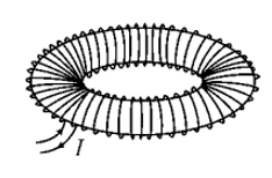

图1 螺绕环

**        下面从毕奥-萨伐尔定律出发，计算载流螺线环的磁场。在计算时,螺线环中的每匝线圈用载流圆线圈代替,即螺线环的匝数就是圆环的个数，并且不考虑载流导线的直径。 建立如图2所示的空间直角坐标系，设xoy平面为螺线环参考平面，螺线环的半径为R1，螺线环的匝数为N，即螺线环由N个均匀分布的载流圆线圈构成，电流为*****I，*****考虑位于螺线环参考平面上方位角α处的载流圆线圈，电流方向如图2所示，载流圆线圈正方向为**$\vec{n}$**,θ为向量 **$\vec{O^{\prime } P}$** 与**$\vec{n}$**的夹角,有 **$\alpha =\frac{2\pi i}{N}\left(i=0,1,\ldotp \ldotp \ldotp ,N-1\right)$ 

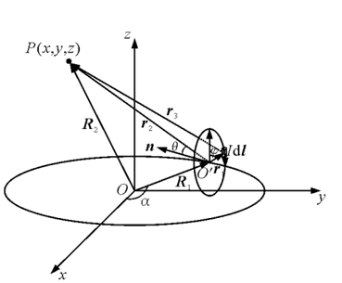

图 2 载流螺线环磁场示意图

**        在图2中，O′为螺线环上任取的一个载流圆线圈的圆心，φ为任一电流线圈平面上线圈圆心到电流元的矢量**$\vec{{r_1 }_{\;} }$** 与电流线圈平面极坐标的极轴的夹角，容易得到圆线圈上任一电流元到P点的位置矢量为:**


$$\vec{r_{\;3} } =\left(x-R_1 \cos \alpha -{r_1 }_{\;} \sin \varphi \cos \alpha \right){\vec{e} }_x +\left(y-R_1 \sin \alpha -{r_1 }_{\;} \sin \varphi \sin \alpha \right){\vec{e} }_y +\left(z-{r_1 }_{\;} \cos \varphi \right){\vec{e} }_z$$


**        而圆环上的电流元为：**


$$\textrm{Id}\vec{l} =Ir_1 d\varphi \left\lbrack \left(\cos \varphi \cos \alpha \right){\vec{e} }_x +\left(\cos \varphi \sin \alpha \right){\vec{e} }_y -\sin \varphi {\vec{e} }_z \right\rbrack =Ir_{\;1} d\varphi \;{\vec{e} }_{\tau }$$


**        则载流圆线圈在P 点的磁感应强度为:**


$$\vec{B} \left(\alpha \right){=\int_0^{2\pi } \frac{\mu_0 Ir_1 d\varphi }{4\pi {r_{\;3} }^3 }\;\vec{e_{\tau } } }_{\;} \times \vec{r_{\;3} }$$


**        根据上式，我们可以利用 MATLAB仿真其磁场的整体分布如下：**

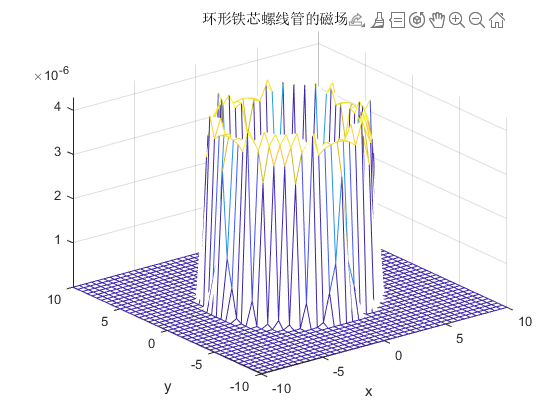

%定义相关常数及网格划分
MU0=4*pi*1e-7;        %真空中的磁导率
I0=1;                 %自定义电流大小
R=5;                  %自定义螺线环半径
r=0.5;                  %自定义螺线环横截面半径
N=100;                  %匝数
C=MU0/(4*pi)*I0;                      %归并常数
Nx=41;Ny=41;Nz=41;                    %观测点网格数
x=linspace(-2*R,2*R,Nx);              %观测点范围
y=linspace(-2*R,2*R,Ny);
z=linspace(-2*R,2*R,Nz);
[X,Y]=meshgrid(x,y);
Bx=zeros(size(X));                    %初始化磁感应强度分量
By=zeros(size(Y));
Bz=zeros(size(X));

%循环计算各网格点上的B(x,y)值
for i=0:N-1
    alpha=2*pi*i/N;                    %螺线环上方位角
    for phi=0:0.005:2*pi
       %电流元到场点的距离分量
       a1=X-R*cos(alpha)-r*sin(phi)*cos(alpha);
       a2=Y-R*sin(alpha)-r*sin(phi)*sin(alpha);
       a3=0-r*cos(phi);
       %圆环上电流元分量
       b1=cos(phi)*cos(alpha);
       b2=cos(phi)*sin(alpha);
       b3=-sin(phi);
       %电流元到场点距离的立方
       r3=sqrt(a1.^2+a2.^2+a3.^2).^3;
       %计算dl和r叉乘结果的x，y，z分量
       dlXr_x=b2.*a3-b3.*a2;
       dlXr_y=b3.*a1-b1.*a3;
       dlXr_z=b1.*a2-b2.*a1;
       %把各段小电流元产生的磁场分量在0到2*pi上累加代替积分
       Bx=Bx+C*0.005*dlXr_x.*r./r3;    %磁感应强度的x分量
       By=By+C*0.005*dlXr_y.*r./r3;    %磁感应强度的y分量
       Bz=Bz+C*0.005*dlXr_z.*r./r3;    %磁感应强度的z分量
    end
end

% 绘制矢量场图
B=sqrt(Bx.^2+By.^2+Bz.^2);       %总磁感应强度大小
meshc(x,y,B)  
title('环形铁芯螺线管的磁场分布');
xlabel('x');
ylabel('y');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **参考文献：**

**                [1] 周鑫,李江珊,吴明和,滕保华.载流螺线环磁场的MATLAB仿真[J].物理通报,2019(01):40-42+48.**